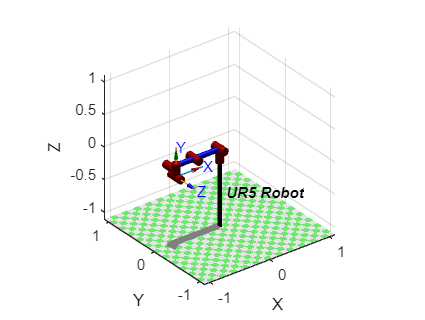

clc;
clear;

syms theta1 theta2 theta3 theta4 theta5 theta6
%theta1=pi/2; theta2=0;  theta3=0; theta4=pi/2;  theta5=-pi/2; theta6=0; 

a1=0; a2 = -0.425; a3 = -0.3922; a4=0; a5=0; a6=0;
d1=0.08946 ; d2=0; d3=0; d4=0.1091; d5=0.09465 ; d6=0.0823;

RigidBody(1) = Link([0  d1   a1   pi/2]);
RigidBody(2) = Link([0  0   a2    0]); 
RigidBody(3) = Link([0  d3   a3    0]);
RigidBody(4) = Link([0  d4   0   pi/2]);
RigidBody(5) = Link([0  d5   a5  -pi/2]);
RigidBody(6) = Link([0  0   0    0]);

UR5Robot = SerialLink(RigidBody);
UR5Robot.name = 'UR5 Robot';
UR5Robot.plot([0 0 0 0 0 0])


% DH parameters of the UR5 robot
fprintf(' DH table of parameters \n')

 DH table of parameters 


UR5Robot.display()

 
UR5Robot = 
 
UR5 Robot:: 6 axis, RRRRRR, stdDH, slowRNE                       
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|    0.08946|          0|     1.5708|          0|
|  2|         q2|          0|     -0.425|          0|          0|
|  3|         q3|          0|    -0.3922|          0|          0|
|  4|         q4|     0.1091|          0|     1.5708|          0|
|  5|         q5|    0.09465|          0|    -1.5708|          0|
|  6|         q6|          0|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+